# Legendre polynomials

wiki: [https://en.wikipedia.org/wiki/Legendre_polynomials](https://en.wikipedia.org/wiki/Legendre_polynomials)


$$$$
P_n\left( x \right) =\frac{1}{2^n}\sum_{k=0}^{\left[ n/2 \right]}{\left( -1 \right) ^k\left( \begin{array}{c}
	n\\
	k\\
\end{array} \right) \left( \begin{array}{c}
	2n-2k\\
	n\\
\end{array} \right) x^{n-2k}}
$$
$$


**example**:

- 
$$$$
P_0\left( x \right) =1
$$
$$


- 
$$$$
P_1\left( x \right) =x
$$
$$


- 
$$$$
P_2\left( x \right) =\frac{3}{2}x^2-\frac{1}{2}
$$
$$


## **Graph**

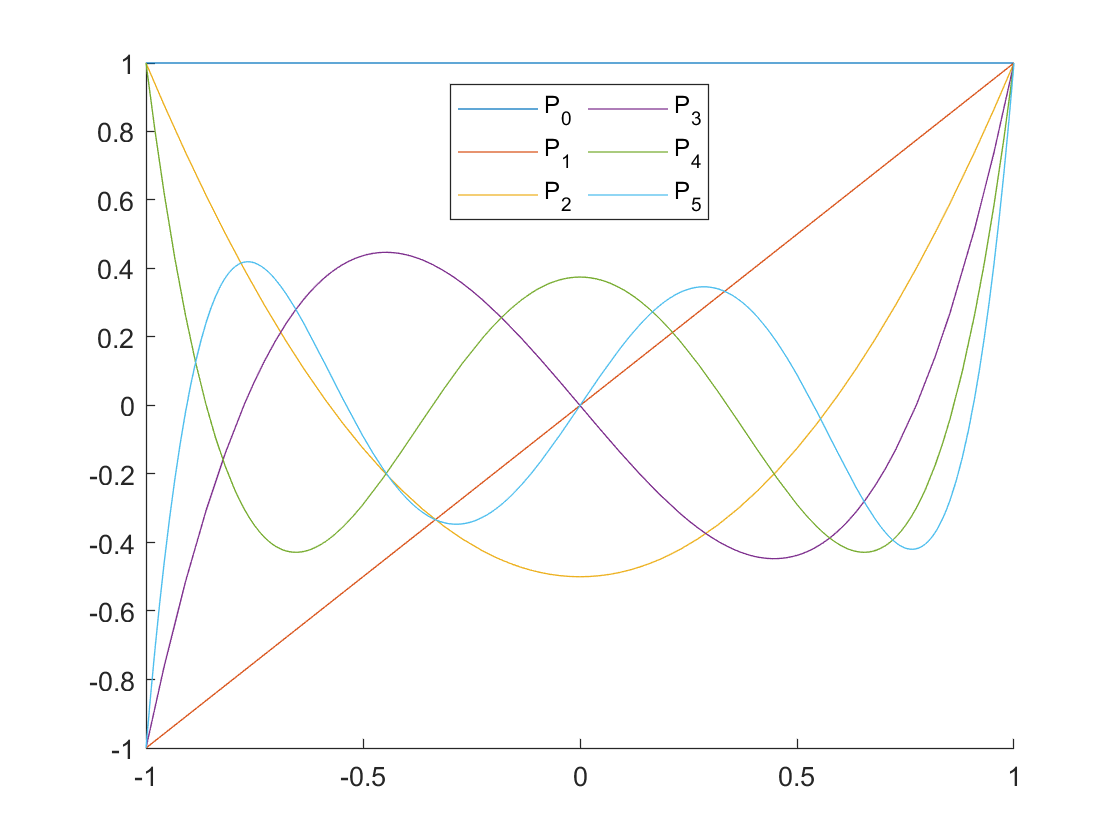

fig = figure();
ax = axes(fig);
ax.NextPlot = 'add';
fp = gobjects(1,6);
for ind1 = 0:5
    [~,hf1] = my_legendre(ind1);
    fp(ind1+1) = fplot(hf1, [-1,1]);
end
legend(fp, {'P_0','P_1','P_2','P_3','P_4','P_5'},...
    'Location','north','NumColumns',2)

## Orthognality

wiki: [https://en.wikipedia.org/wiki/Legendre_polynomials#Orthogonality](https://en.wikipedia.org/wiki/Legendre_polynomials#Orthogonality)


$$$$
\int_{-1}^1{P_m\left( x \right) P_n\left( x \right) dx}=\frac{2}{2n+1}\delta _{mn}
$$
$$


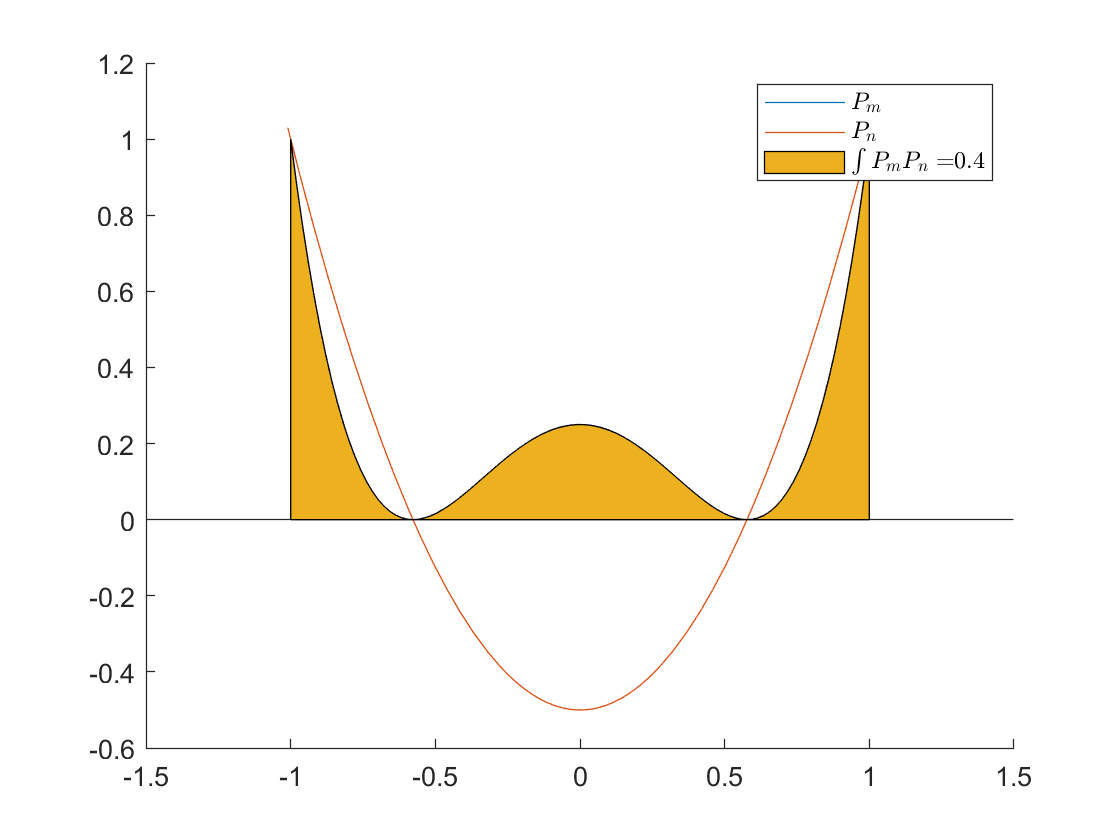

M = 2;
N = 2;
[~,hf1] = my_legendre(M);
[~,hf2] = my_legendre(N);
hf3 = @(x) hf1(x).*hf2(x);
value = integral(hf3, -1, 1);

fig = figure();
ax = axes(fig);
ax.NextPlot = 'add';
fp1 = fplot(hf1, [-1.01,1.01]);
fp2 = fplot(hf2, [-1.01,1.01]);
x = linspace(-1,1,100);
harea = area(x, hf3(x));
tmp1 = {'$P_m$', '$P_n$', ['$\int{P_mP_n=}',num2str(value,4), '$']};
legend([fp1,fp2,harea], tmp1, 'Interpreter','latex')

## Recursion relations

wiki: [https://en.wikipedia.org/wiki/Legendre_polynomials#Recursion_relations](https://en.wikipedia.org/wiki/Legendre_polynomials#Recursion_relations)


$$$$
\frac{x^2-1}{n}\frac{d}{dx}P_n\left( x \right) =xP_n\left( x \right) -P_{n-1}\left( x \right) 
$$
$$


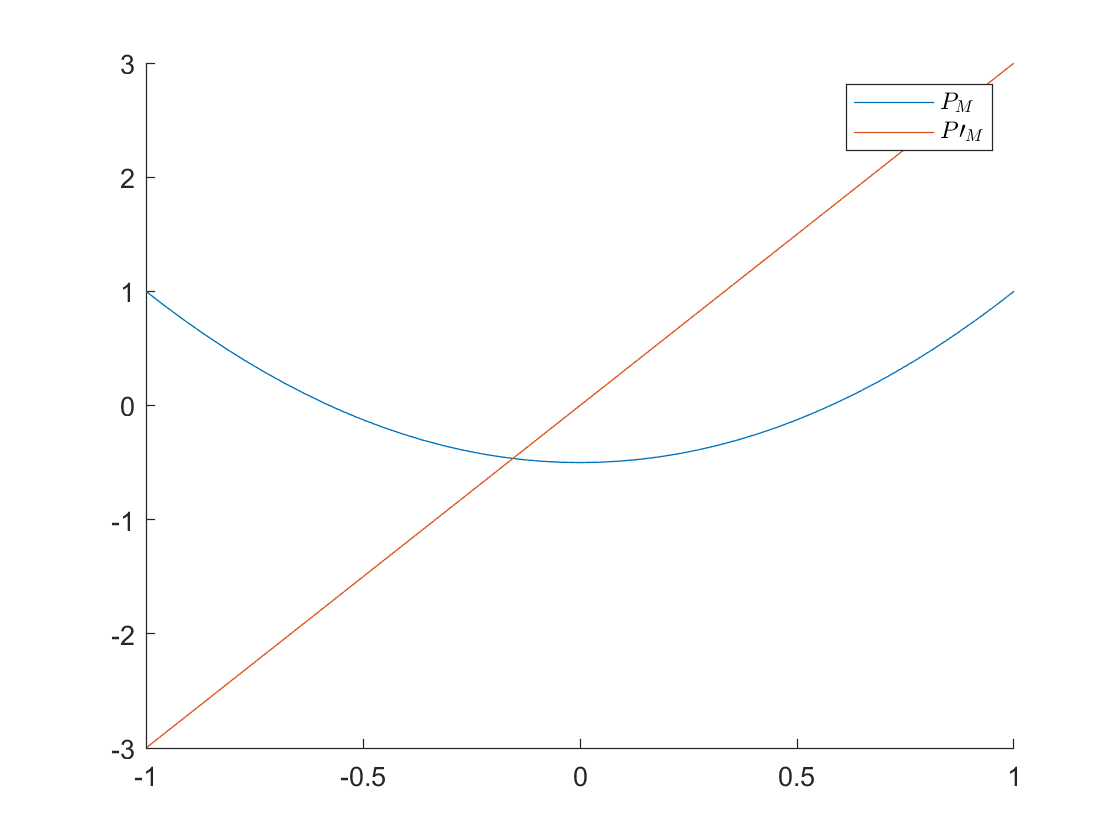

M = 2;
[~,hf1] = my_legendre(M);
hf2 = my_legendre_first_derivative(M);

fig = figure();
ax = axes(fig);
ax.NextPlot = 'add';
fp1 = fplot(hf1, [-1,1]);
fp2 = fplot(hf2, [-1,1]);
legend([fp1,fp2], {'$P_M$', '$P\prime_M$'}, 'Interpreter','latex')

## Gaussian Quadrature Integral (Gaussian-Legendre)

wiki: [https://en.wikipedia.org/wiki/Gaussian_quadrature](https://en.wikipedia.org/wiki/Gaussian_quadrature)


$$$$
\int_a^b{f\left( x \right) dx}=\frac{b-a}{2}\int_{-1}^1{g\left( x \right) dx};\quad g\left( x \right) =f\left( \frac{b-a}{2}x+\frac{b+a}{2} \right) 
$$
$$



$$$$
\int_{-1}^1{g\left( x \right) dx}\approx \sum_{i=1}^n{w_ig\left( x_i \right)}
$$
$$



$$$$
w_i=\frac{2}{\left( 1-x_{i}^{2} \right) \left[ P_{n}^{'}\left( x_i \right) \right] ^2}
$$
$$


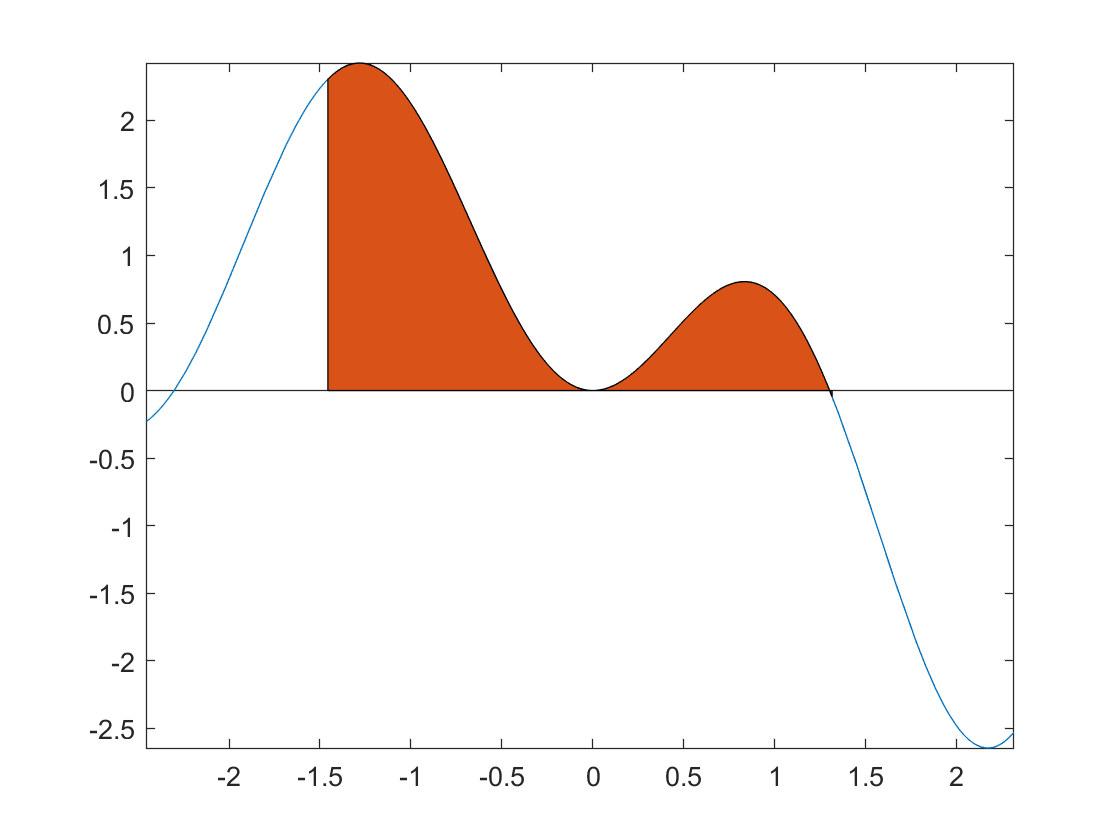

hf1 = @(x) (3-x-x.^2).*sin(x).^2; %integral function; hf short for function handle
a = -1-rand()/2; %lower limit
b = 1+rand()/2; %upper limit

figure()
fplot(hf1, [a-1,b+1])
hold on;
area(linspace(a,b), hf1(linspace(a,b)))
hold off


ret1 = integral(hf1, a, b); %doc('integral')
disp(['built-in integral: ', num2str(ret1,14)])

built-in integral: 2.5167613796195



ret1 = my_gaussian_quadrature(hf1, a, b, 5);
disp(['Gaussian-Quadrature integral: ', num2str(ret1,14)])

Gaussian-Quadrature integral: 2.5164503495063


function ret = my_gaussian_quadrature(hf1, a, b, num_order)
%reference: https://en.wikipedia.org/wiki/Gaussian_quadrature
% hf1(function handle)
% a(float)
% b(float)
% num_order(int)
% (ret)float
max_order = 15;
if num_order>max_order
    disp(['root of high order Legendre Polynomial is unstable, set num_order=',num2str(max_order)]);
    disp('detail see: https://math.stackexchange.com/questions/2636801/high-accuracy-root-finder-of-legendre-polynomials-derivatives')
    num_order = max_order;
end

root_legendre = my_legendre_root(num_order);
hf2 = my_legendre_first_derivative(num_order);
weight = 2./((1-root_legendre.^2).*hf2(root_legendre).^2);

x = root_legendre*(b-a)/2 + (b+a)/2;
ret = (b-a)/2 * sum(weight.*hf1(x));
end


function ret = my_legendre_first_derivative(N)
% reference: https://en.wikipedia.org/wiki/Legendre_polynomials#Recursion_relations
% N(int)
% (ret)(function handle)
if N==0
    ret = @(x) zeros(size(x));
else
    [~,hf1] = my_legendre(N);
    [~,hf2] = my_legendre(N-1);
    ret = @(x) N*(x.*hf1(x) - hf2(x))./(x.^2-1);
end
end